# s-curve | vertical

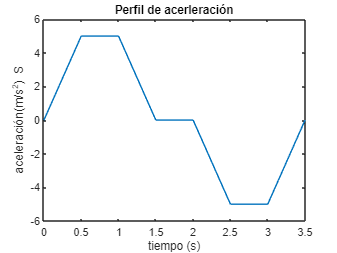

clear
delta=0.01;
m=10;
t=0:delta:3.5;
adef=(m*ctramp(t)-m*ctramp(t-3.5/7)-m*ctramp(t-2*3.5/7)).*(t<3*3.5/7)...
    +(-1)*(m*ctramp(t-4*3.5/7)-m*ctramp(t-(5*3.5/7))-m*ctramp(t-(6*3.5/7))).*(t>4*3.5/7);

plot(t,adef)
title('Perfil de acerleración')
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2) S')

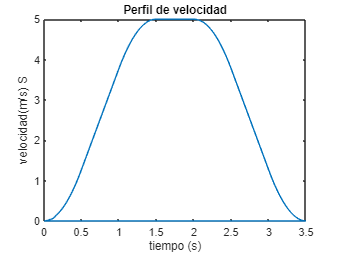


vdef=zeros(length(adef));
r=0;
for i=1:length(vdef)
    index=find(t<=r);
    vdef(i) = delta*sum(adef(index));
    r=r+delta;
end
plot(t,vdef)
title('Perfil de velocidad')
xlabel('tiempo (s)')
ylabel('velocidad(m/s) S')

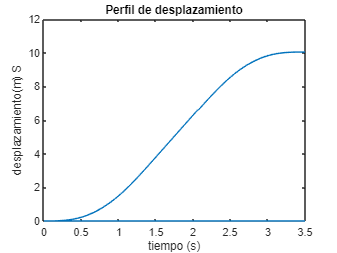


sdef=zeros(length(adef));
r=0;
for i=1:length(sdef)
    index=find(t<=r);
    sdef(i) = delta*sum(vdef(index));
    r=r+delta;
end
plot(t,sdef)
title('Perfil de desplazamiento')
xlabel('tiempo (s)')
ylabel('desplazamiento(m) S')


%{
Perfil de fuerza 
masa=366.7;
fdef=adef*masa+366.7*9.81;

plot(t,fdef)    
title('Perfil de fuerza')
xlabel('tiempo (s)')
ylabel('fuerza (N) S')

%Perfil de torque 
fi=masa*9.81-fdef;
torquedef=(fi+masa*9.81)*1.22;
plot(t,torquedef)
title('Perfil de torque')
xlabel('tiempo (s)')
ylabel('torque (N m) S')
%}

# trapecio

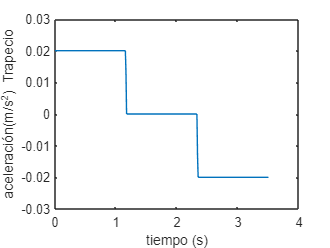

clear
delta=0.01;
m=2;
t=0:delta:3.5;
v=m*ctramp(t)-m*ctramp(t-3.5/3)-m*ctramp(t-2*3.5/3);
a=diff(v);

ta=linspace(0,3.5,350);
plot(ta,a)
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2) Trapecio')

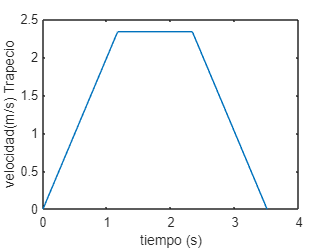


%v=zeros(length(a));
%r=0;
%for i=1:length(v)
%    index=find(t<=r);
%    v(i) = delta*sum(a(index));
%    r=r+delta;
%end
plot(t,v)
xlabel('tiempo (s)')
ylabel('velocidad(m/s) Trapecio')

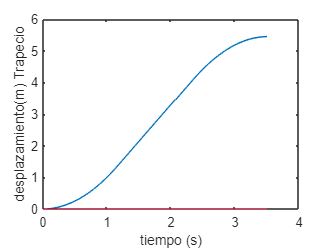


s=zeros(length(a));
r=0;
for i=1:length(s)
    index=find(t<=r);
    s(i) = delta*sum(v(index));
    r=r+delta;
end
plot(ta,s)
xlabel('tiempo (s)')
ylabel('desplazamiento(m) Trapecio')

# Triángulo

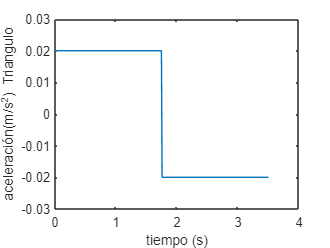

clear
delta=0.01;
m=2;
t=0:delta:3.5;
v=m*ctramp(t)-2*m*ctramp(t-3.5/2);
a=diff(v);
ta=linspace(0,3.5,350);
plot(ta,a)
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2) Triangulo')

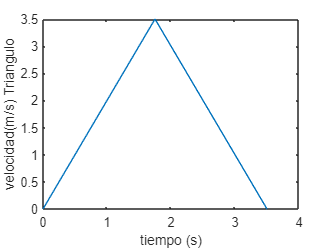


%v=zeros(length(a));
%r=0;
%for i=1:length(v)
%    index=find(t<=r);
%    v(i) = delta*sum(a(index));
%    r=r+delta;
%end
plot(t,v)
xlabel('tiempo (s)')
ylabel('velocidad(m/s) Triangulo')

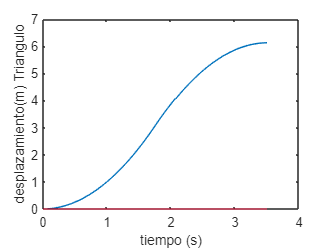


s=zeros(length(a));
r=0;
for i=1:length(s)
    index=find(t<=r);
    s(i) = delta*sum(v(index));
    r=r+delta;
end
plot(ta,s)
xlabel('tiempo (s)')
ylabel('desplazamiento(m) Triangulo')

# s-curve | horizontal

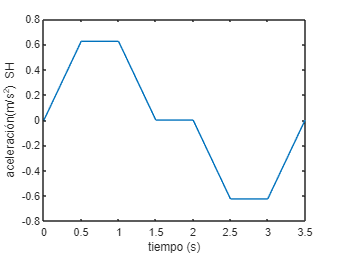

delta=0.01;
m=1.25;
t=0:delta:3.5;
ah=(m*ctramp(t)-m*ctramp(t-3.5/7)-m*ctramp(t-2*3.5/7)).*(t<3*3.5/7)...
    +(-1)*(m*ctramp(t-4*3.5/7)-m*ctramp(t-(5*3.5/7))-m*ctramp(t-(6*3.5/7))).*(t>4*3.5/7);

plot(t,ah)
xlabel('tiempo (s)')
ylabel('aceleración(m/s^2) SH')

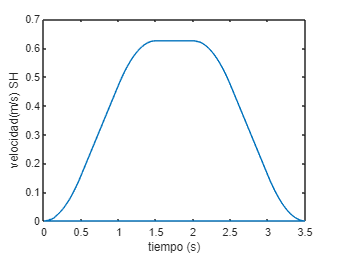


vh=zeros(length(ah));
r=0;
for i=1:length(vh)
    index=find(t<=r);
    vh(i) = delta*sum(ah(index));
    r=r+delta;
end
plot(t,vh)
xlabel('tiempo (s)')
ylabel('velocidad(m/s) SH')

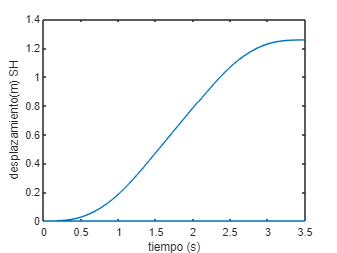


sh=zeros(length(ah));
r=0;
for i=1:length(sh)
    index=find(t<=r);
    sh(i) = delta.*sum(vh(index));
    r=r+delta;
end
plot(t,sh)
xlabel('tiempo (s)')
ylabel('desplazamiento(m) SH')


%{
Perfil de fuerza 
masa=366.7;
fH=a*masa;

plot(t,fH)
title('Perfil de fuerza Horizontal')
xlabel('tiempo (s)')
ylabel('fuerza (N) S')

%Perfil de torque 
torqueH=masa*9.81*s;
plot(t,torqueH)
title('Perfil de torque Horizontal')
xlabel('tiempo (s)')
ylabel('torque (N m) S')
%}

# Pérfiles de fuerza elevación 

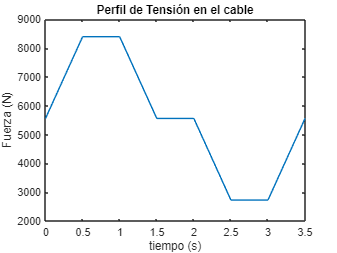

%Tensión en la cuerda 
masac=366.7;
masab=200;
N=masac*(adef+9.81);
T=masab*(adef+9.81)+N;

plot(t,T)
title('Perfil de Tensión en el cable')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

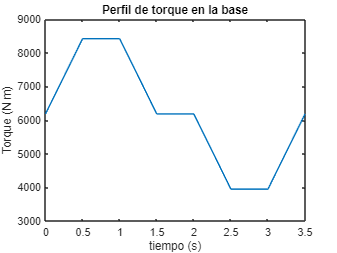


%Torque en la base 
Mb=N*1.22+masab*9.81*3/4*1.22;

plot(t,Mb)
title('Perfil de torque en la base')
xlabel('tiempo (s)')
ylabel('Torque (N m)')

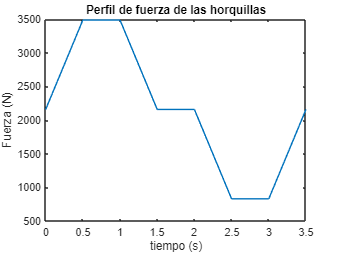


%Fuerza de las horquillas
ue=0.6;
Ft=masac*ah+ue*N;
plot(t,Ft)
title('Perfil de fuerza de las horquillas')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')

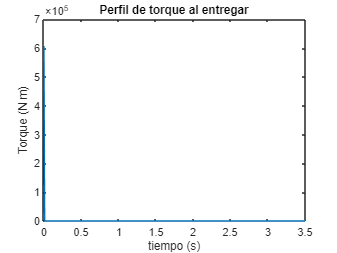


%Torque en la entrega
Me=N*sh;
plot(t,Me)
title('Perfil de torque al entregar')
xlabel('tiempo (s)')
ylabel('Torque (N m)')